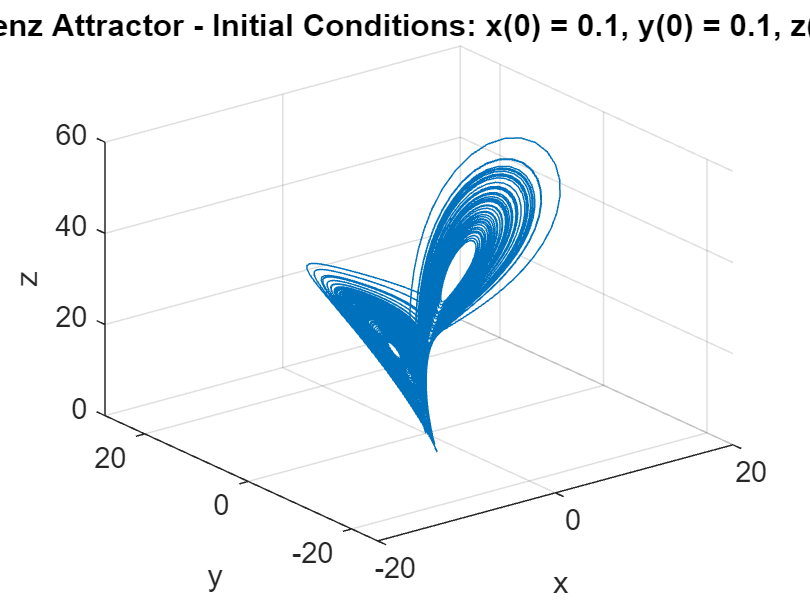

% Constants
rho = 28;
sigma = 10;
beta = 8/3;
h = 0.01;
t_final = 100;

% Initial conditions for part (a)
x0_a = 0.1;
y0_a = 0.1;
z0_a = 0;
initial_conditions_a = [x0_a, y0_a, z0_a];

% Initial conditions for part (b)
x0_b = 0.1;
y0_b = 0.100001;
z0_b = 0;
initial_conditions_b = [x0_b, y0_b, z0_b];

% Time vector
t = 0:h:t_final;

% Define the Lorenz system
lorenz = @(t, Y) [sigma*(Y(2) - Y(1)); ...
                  Y(1)*(rho - Y(3)) - Y(2); ...
                  Y(1)*Y(2) - beta*Y(3)];

% Part (a)
Y_a = rk4_solver(lorenz, t, initial_conditions_a, h);

% Part (b)
Y_b = rk4_solver(lorenz, t, initial_conditions_b, h);

% Plot trajectories in phase space for part (a)
figure;
plot3(Y_a(:,1), Y_a(:,2), Y_a(:,3));
title('Lorenz Attractor - Initial Conditions: x(0) = 0.1, y(0) = 0.1, z(0) = 0');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

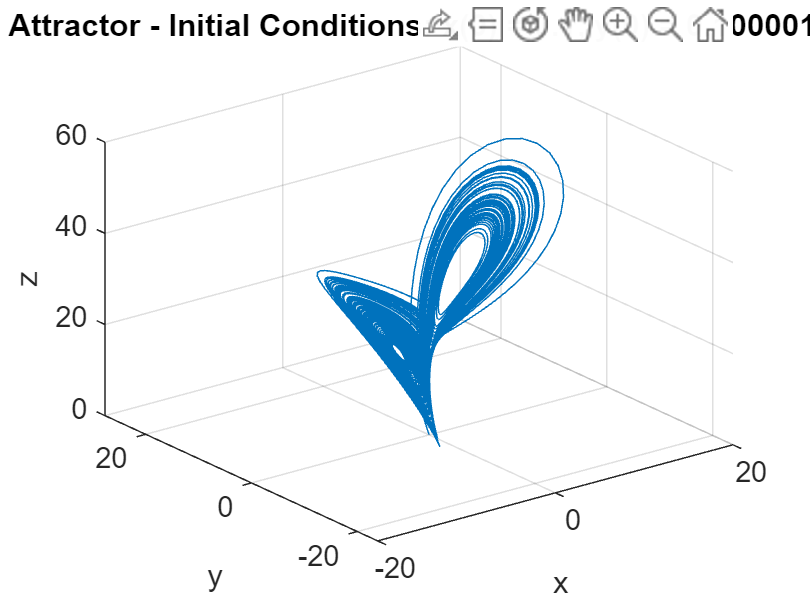


% Plot trajectories in phase space for part (b)
figure;
plot3(Y_b(:,1), Y_b(:,2), Y_b(:,3));
title('Lorenz Attractor - Initial Conditions: x(0) = 0.1, y(0) = 0.100001, z(0) = 0');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

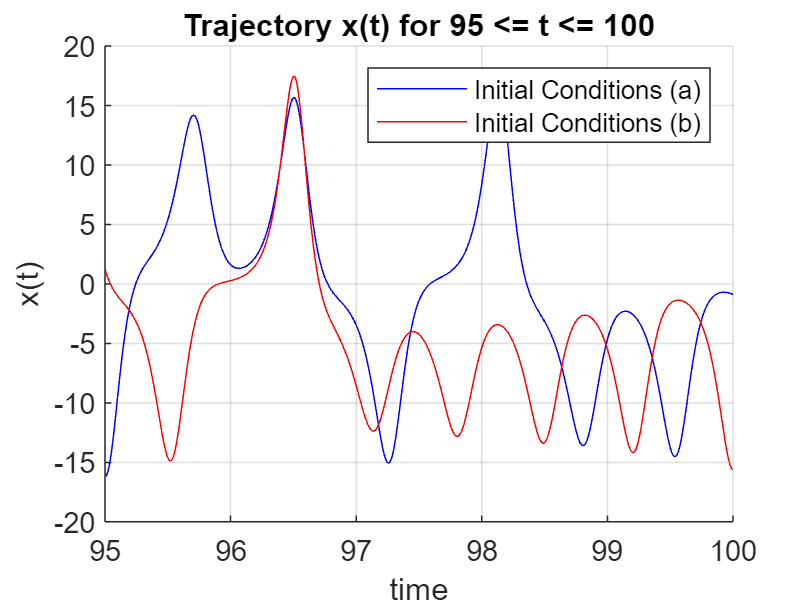


% Part (c) - Plot x(t) for 95 <= t <= 100
figure;
hold on;
plot(t(t >= 95 & t <= 100), Y_a(t >= 95 & t <= 100, 1), 'b');
plot(t(t >= 95 & t <= 100), Y_b(t >= 95 & t <= 100, 1), 'r');
title('Trajectory x(t) for 95 <= t <= 100');
xlabel('time');
ylabel('x(t)');
legend('Initial Conditions (a)', 'Initial Conditions (b)');
grid on;
hold off;

function Y = rk4_solver(lorenz, t, initial_conditions, h)
    N = length(t);
    Y = zeros(N, 3);
    Y(1, :) = initial_conditions;
    
    for i = 1:N-1
        k1 = h * lorenz(t(i), Y(i, :))';
        k2 = h * lorenz(t(i) + h/2, Y(i, :) + k1/2)';
        k3 = h * lorenz(t(i) + h/2, Y(i, :) + k2/2)';
        k4 = h * lorenz(t(i) + h, Y(i, :) + k3)';
        Y(i+1, :) = Y(i, :) + (k1 + 2*k2 + 2*k3 + k4) / 6;
    end
end